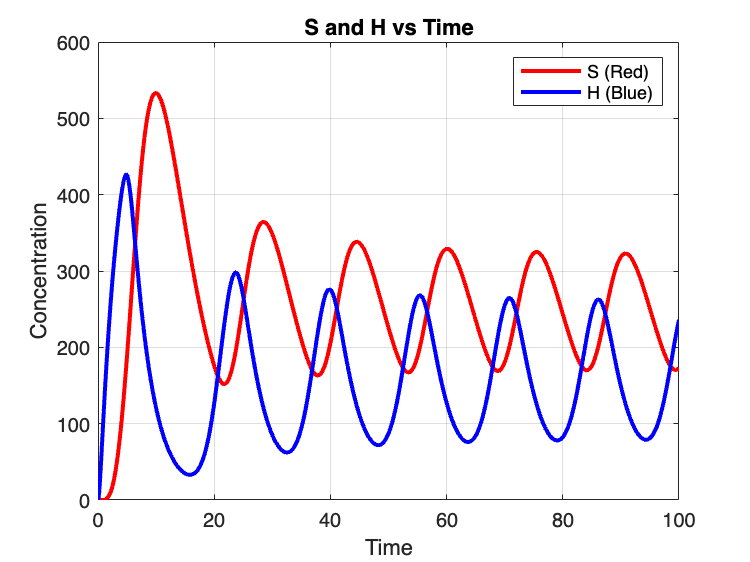

% 参数定义（需根据实际情况调整）
alpha_S0 = 0.1;    % α_S0
alpha_S = 30.5;     % α_S
K_H = 326;         % K_H
n1 = 3;          % n1
delta_m = 0.3;   % δ_m

alpha_H0 = 0.1;    % α_H0
alpha_H = 183;     % α_H
K_S = 185;         % K_S
n2 = 4.8;          % n2

beta = 3.7;      % β
delta_S = 0.2;   % δ_S
delta_H = 3.8;   % δ_H

% 时间范围
tspan = [0 100]; % 模拟时间范围（例如0到100）

% 初始条件（全部设为0）
y0 = [0; 0; 0; 0]; % [mS; mH; S; H]

% 调用ODE求解器
[t, y] = ode45(@(t,y) model(t,y,alpha_S0,alpha_S,K_H,n1,delta_m,...
                     alpha_H0,alpha_H,K_S,n2,beta,delta_S,delta_H), tspan, y0);

% 提取结果
S = y(:,3);
H = y(:,4);

% 绘制结果（S和H在同一张图）
figure;
plot(t, S, 'r', 'LineWidth', 2); hold on;
plot(t, H, 'b', 'LineWidth', 2);
title('S and H vs Time');
xlabel('Time'); ylabel('Concentration');
legend('S (Red)', 'H (Blue)');
grid on;

% --- 新增代码 ---
% 将图形保存为SVG文件
saveas(gcf, 'S_and_H_vs_Time.svg');
% -----------------

hold off;


% 微分方程模型函数
function dydt = model(~, y, alpha_S0, alpha_S, K_H, n1, delta_m, ...
                      alpha_H0, alpha_H, K_S, n2, beta, delta_S, delta_H)
    
    mS = y(1);
    mH = y(2);
    S = y(3);
    H = y(4);
    
    % 计算导数
    dmS_dt = alpha_S0 + alpha_S*(H^n1)/(K_H^n1 + H^n1) - delta_m*mS;
    dmH_dt = alpha_H0 + alpha_H*(K_S^n2)/(K_S^n2 + S^n2) - delta_m*mH;
    dS_dt = beta*mS - delta_S*S;
    dH_dt = beta*mH - delta_H*H;
    
    dydt = [dmS_dt; dmH_dt; dS_dt; dH_dt];
end